Con questo live script da formalizzare a dovere viene provata la corrispondenza tra i valori analitici e quelli empirici trovati tramite la simulazione.

Il test viene effettuato con i seguenti parametri:

- numero di server nel cloudlet: 3

- lambda in ingresso classe 1: 6

- lambda in ingresso classe 2: 6.25

- mu cloudlet classe 1: 

- mu cloudlet classe 2: 

- mu cloud classe 1:

- mu cloud classe 2: 

- distribuzione servizi: esponenziale

lambdaClassOne = 6;
lambdaClassTwo = 6.25;
cloudletMuClassOne = 0.45;
cloudletMuClassTwo = 0.27;
cloudMuClassOne = 0.25;
cloudMuClassTwo = 0.22;

Per prima cosa risolviamo la catena di markov relativa al sistema al fine di trovare il lambda entrante nel cloudlet e quello del cloud

lambda = lambdaClassOne + lambdaClassTwo;
[ploss, avgPopulationCloudlet] = plossCalculator;
fprintf('Probabilità di entrare nel cloudlet: \t%f', vpa(1-ploss));

Probabilità di entrare nel cloudlet: 	0.079923

fprintf('probabilità di entrare nel cloud: \t%f', vpa(ploss));

probabilità di entrare nel cloud: 	0.920077

fprintf('lambda entrante nel cloudlet: \t\t%f', vpa(lambda*(1-ploss)));

lambda entrante nel cloudlet: 		0.979054

fprintf('lambda entrante nel cloud: \t\t%f', vpa(lambda*ploss));

lambda entrante nel cloud: 		11.270946

In questo caso si stanno considerando gli arrivi di prima e seconda classe come facenti parte dello stesso flusso. Analisi relative alla due singole classi saranno fatte successivamente.

I sistemi cloudlet e cloud non hanno coda. Questo vuol dire che un job che entra nel sistema deve essere immediatamente servito. In tal caso quindi i tempi di servizio dipendono fortemente dalla classe di appartenenza. Volendo scrivere quindi i tempi di servizio si ha che

PbeingClassOne = lambdaClassOne/lambda;
PbeingClassTwo = lambdaClassTwo/lambda;
cloudletServiceTimeClassOne = 1/cloudletMuClassOne;
cloudletServiceTimeClassTwo = 1/cloudletMuClassTwo;
cloudletST = PbeingClassOne*cloudletServiceTimeClassOne + ... 
             PbeingClassTwo*cloudletServiceTimeClassTwo;
cloudServiceTimeClassOne = 1/cloudMuClassOne;
cloudServiceTimeClassTwo = 1/cloudMuClassTwo;
cloudST =    PbeingClassOne*cloudServiceTimeClassOne + ... 
             PbeingClassTwo*cloudServiceTimeClassTwo;
globalST = ploss*cloudST + (1-ploss)*cloudletST;
classOneST = cloudletServiceTimeClassOne*(1-ploss) + ...
             cloudServiceTimeClassOne*(ploss);
classTwoST = cloudletServiceTimeClassTwo*(1-ploss) + ...
             cloudServiceTimeClassTwo*(ploss);
fprintf("Global Service time: \t\t\t%f", globalST);

Global Service time: 			4.174376

fprintf("Global Service time cloudlet: \t\t%f", cloudletST);

Global Service time cloudlet: 		2.978080

fprintf("Global Service time cloud: \t\t%f", cloudST);

Global Service time cloud: 		4.278293

fprintf("Global Service time class 1: \t\t%f", classOneST);

Global Service time class 1: 		3.857915

fprintf("Global Service time class 2: \t\t%f", classTwoST);

Global Service time class 2: 		4.478179

fprintf("Service time cloudlet Class 1: \t\t%f", cloudletServiceTimeClassOne);

Service time cloudlet Class 1: 		2.222222

fprintf("Service time cloudlet Class 2: \t\t%f", cloudletServiceTimeClassTwo);

Service time cloudlet Class 2: 		3.703704

fprintf("Service time cloud Class 1: \t\t%f", cloudServiceTimeClassOne);

Service time cloud Class 1: 		4.000000

fprintf("Service time cloud Class 2: \t\t%f", cloudServiceTimeClassTwo);

Service time cloud Class 2: 		4.545455

Come si può vedere dalla chiamata di funzione, plossCalculator permette di calcolare anche la media di popolazione all'interno del cloudlet. Per calcolare quella del cloud è sufficiente usare il teorema di Little

avgPopulationCloud = lambda*(ploss)*cloudST;
avgPopulationGlobal = avgPopulationCloud + avgPopulationCloudlet;
avgPopulationClassOne = avgPopulationGlobal*PbeingClassOne;
avgPopulationClassTwo = avgPopulationGlobal*PbeingClassTwo;

fprintf('Popolazione media globale: \t\t%f', avgPopulationGlobal);

Popolazione media globale: 		51.136112

fprintf('Popolazione media cloudlet: \t\t%f', avgPopulationCloudlet);

Popolazione media cloudlet: 		2.915702

fprintf('Popolazione media cloud: \t\t%f', avgPopulationCloud);

Popolazione media cloud: 		48.220410

fprintf('Popolazione media classe 1: \t\t%f', avgPopulationClassOne);

Popolazione media classe 1: 		25.046259

fprintf('Popolazione media classe 2: \t\t%f', avgPopulationClassTwo);

Popolazione media classe 2: 		26.089853

fprintf('Popolazione media cloudlet classe 1: \t%f', avgPopulationCloudlet*PbeingClassOne);

Popolazione media cloudlet classe 1: 	1.428099

fprintf('Popolazione media cloudlet classe 2: \t%f', avgPopulationCloudlet*PbeingClassTwo);

Popolazione media cloudlet classe 2: 	1.487603

fprintf('Popolazione media cloud classe 1: \t%f', avgPopulationCloud*PbeingClassOne);

Popolazione media cloud classe 1: 	23.618160

fprintf('Popolazione media cloud classe 2: \t%f', avgPopulationCloud*PbeingClassTwo);

Popolazione media cloud classe 2: 	24.602250

A Questo punto è possibile prendere in considerazione i valori della simulazione.

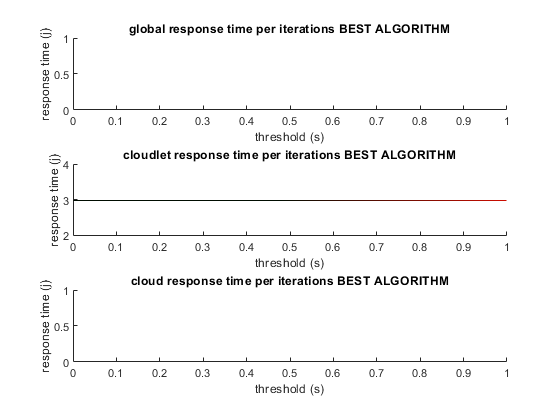

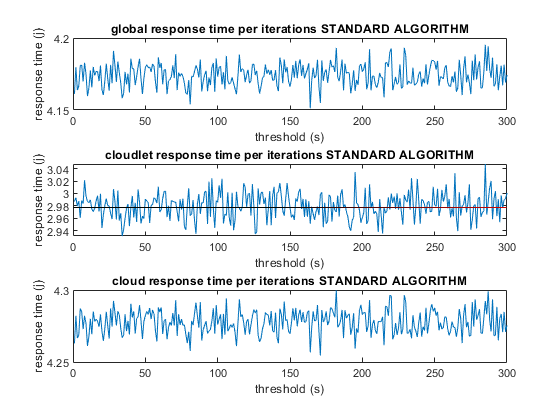

plotSteadyState